%Message Signal Parameters
Am = 1; %Volts (V)
Fm = 10; %Hertz (Hz)

%Carrier Signal Parameters
Ac = 3; %Volts (V)
Fc = 100; %Hertz (Hz)

%Frequency Deviation Value
freqDev = 50; %Hertz (Hz)

%Sampling Parameters
Fs = 1000; %Hertz (Hz)
Ts = 1/Fs; %Seconds (s)

%Time Vector for Simulation
t = 0:Ts:1; %Seconds (s)

%Frequency Vector for Simulation
fVector = linspace(-Fs/2, Fs/2, length(t)); %Hertz (Hz)

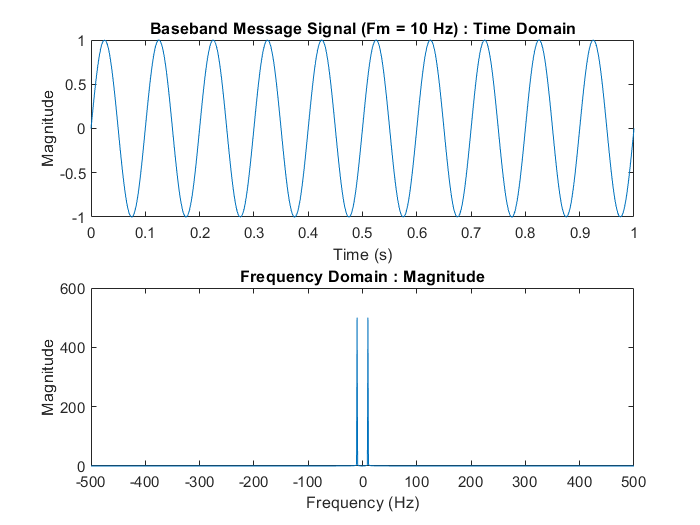

%Baseband Message Signal Generation
baseSig = Am*sin(2*pi*Fm*t); %Volts (V)

%Fourier Transform Calculation for Baseband Message Signal
baseSigFFT = fftshift(fft(baseSig));

%Plotting Message Signal
figure(1);

%Time Domain Plot
subplot(2, 1, 1);
plot(t, baseSig);
title('Baseband Message Signal (Fm = 10 Hz) : Time Domain');
xlabel('Time (s)');
ylabel('Magnitude');

%FFT Magnitude Plot
subplot(2, 1, 2);
plot(fVector, abs(baseSigFFT));
title('Frequency Domain : Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

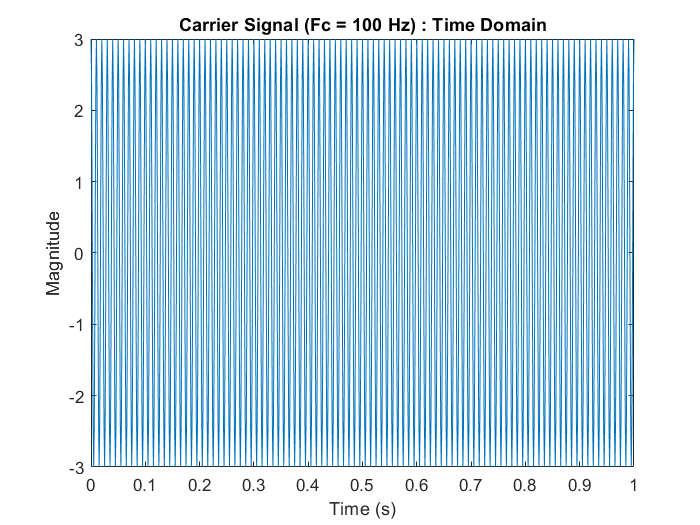

%Carrier Signal Generation
carSig = Ac*cos(2*pi*Fc*t);

%Plotting Carrier Signal
figure(2);

%Time Domain Plot
plot(t, carSig);
title('Carrier Signal (Fc = 100 Hz) : Time Domain');
xlabel('Time (s)');
ylabel('Magnitude');

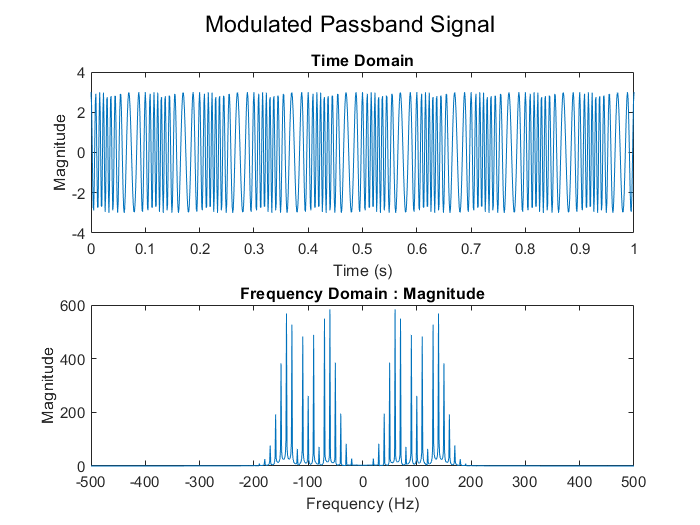

%Modulated Passband Signal Generation

%Using the created function for Frequency Modulation
modSig = fmModulator(baseSig, Ac, Fc, freqDev, Fs);

%Fourier Transform Calculation for Modulated Signal
modSigFFT = fftshift(fft(modSig));

%Plotting Modulated Signal
figure(3);
sgtitle('Modulated Passband Signal');

%Time Domain Plot
subplot(2, 1, 1);
plot(t, modSig);
title('Time Domain');
xlabel('Time (s)');
ylabel('Magnitude');

%FFT Magnitude Plot
subplot(2, 1, 2);
plot(fVector, abs(modSigFFT));
title('Frequency Domain : Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

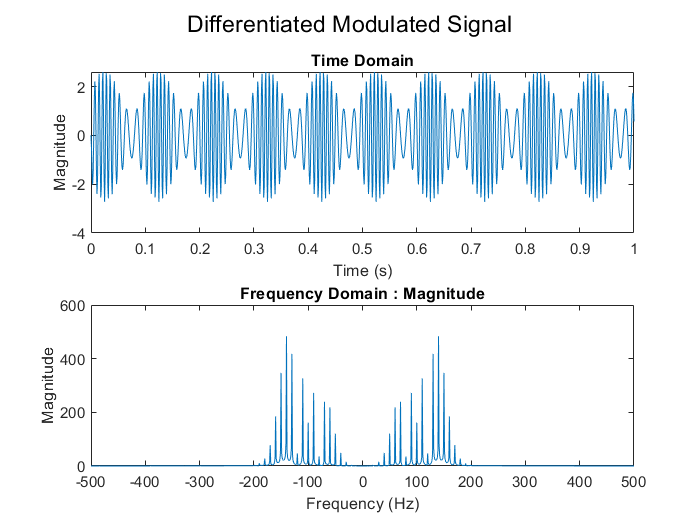

%Demodulating Modulated Passband Signal

%Using the created function for Frequency Demodulation
[diffSig, demodSig] = fmDemodulator(modSig, Am);

%Fourier Transform Calculation for Differentiated Modulated Signal
diffSigFFT = fftshift(fft(diffSig));

%Plotting Demodulated Signal
figure(4);
sgtitle('Differentiated Modulated Signal');

%Time Domain Plot
subplot(2, 1, 1);
plot(t, diffSig);
title('Time Domain');
xlabel('Time (s)');
ylabel('Magnitude');

%FFT Magnitude Plot
subplot(2, 1, 2);
plot(fVector, abs(diffSigFFT));
title('Frequency Domain : Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

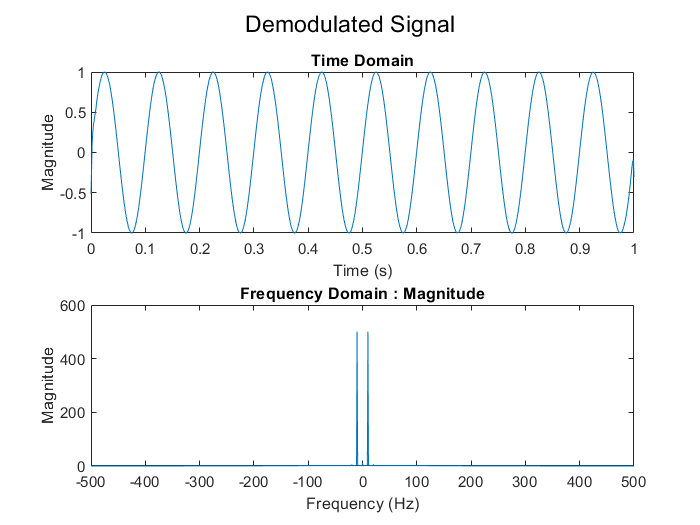


%Fourier Transform Calculation for Demodulated Signal
demodSigFFT = fftshift(fft(demodSig));

%Plotting Demodulated Signal
figure(5);
sgtitle('Demodulated Signal');

%Time Domain Plot
subplot(2, 1, 1);
plot(t, demodSig);
title('Time Domain');
xlabel('Time (s)');
ylabel('Magnitude');

%FFT Magnitude Plot
subplot(2, 1, 2);
plot(fVector, abs(demodSigFFT));
title('Frequency Domain : Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude');